# Numeros aleatorios

La generación de números aleatorios es parte fundamental en métodos Monte Carlo, así como en esquemas criptográficos vigentes.  Desafortunadamente, la generación de números aleatorios es complicada en una computadora, sin embargo, es posible generar (de manera determinística) números que parecen ser aleatorios.  A estos números los llamamos pseudo-aleatorios.

Generación de números pseudo-aleatorios:

- Métodos tradicionales

- Métodos criptográficamente seguros

Generemos algunos números aleatorios uniformemente distribuídos.

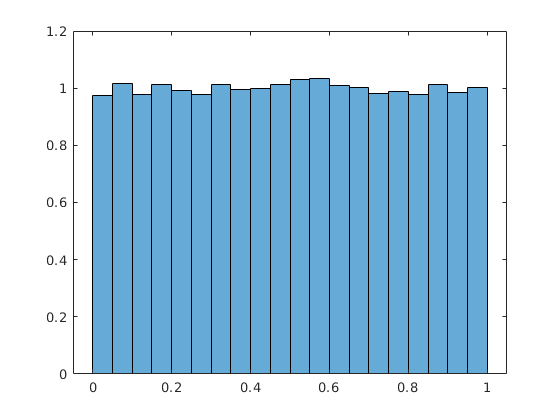

clear;


N = 50000;
nn = 20;

% Era el default de Matlab hace unos anios
rng(0,'v4');  % CMG
pd = makedist('Uniform',0,1);
us = random(pd,1,N);

histogram(us,nn,'Normalization','pdf');

us(1:2)

ans =     0.2190    0.0470


## Generador multiplicativo congruente

El generador es

$x_i = a\:x_{i-1}\:\text{mod}\:m$, $0<x_i<m$,

donde $a$ es el multiplicador, $m$ el módulo, y $x_0$ la semilla.  Esto genera una secuencia conocida como secuencia de Lehmer entre $0$ y $m$.  Podemos normalizar y obtener números pseudoaleatorios uniformemente distribuídos entre 0 y 1.  Implementemos el código.

clear;

% Definimos los parametros del generador
a = 7^5;
m = 2^31-1;
x0 = mod(470211272/a,m);

x1 = mod(a*x0,m);
u1 = x1/m

u1 = 0.2190

x2 = mod(a*x1,m);
u2 = x2/m

u2 = 0.0470

Hagamos un pequeño script para generar una cadena de números aleatorios

clear;

% Cantidad de numeros aleatorios
N = 50000;

% "Alocar" en memoria
x = zeros(1,N);

% Parametros del generador
a = 7^5;   % Multiplicador
m = 2^31-1; % Modulo
x(1) = mod(470211272/a,m);  % Semilla

% Aqui ocurre la magia!
for ii = 2:N
    x(ii) = mod(a*x(ii-1),m);
end

% Aqui tenemos numeros aleatorios U(0,1)
u = x(2:N)./m;

histogram(u,20,'Normalization','pdf')

rng(0,'v4')
rand(1,10)

ans =     0.2190    0.0470    0.6789    0.6793    0.9347    0.3835    0.5194    0.8310    0.0346    0.0535


u(1:10)

ans =     0.2190    0.0470    0.6789    0.6793    0.9347    0.3835    0.5194    0.8310    0.0346    0.0535


## Generación de números aleatorios con otra distribución - método de la transformada inversa

Para este método utlizamos

$X=F_X^{-1}(U)$, con $U$~ Uniforme$(0,1)$.

Ahora generaremos números aleatorios con distribución exponencial y parámetro $\lambda$.

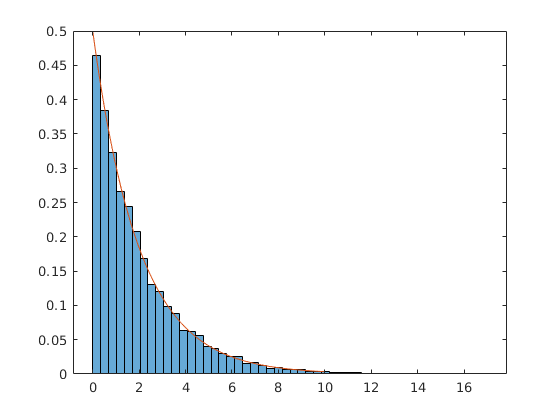

clear;

N = 10000;
nn = 50;

% Numeros distribuidos U(0,1)
rng('default');
pd = makedist('Uniform',0,1);
U = random(pd, 1, N);

% La inversa de la acumulada
llamb = 0.5;
iFX = (-1/llamb) * log(1-U);

% Curva teorica
x = 0:0.01:10;
xpdf = llamb * exp(-llamb*x);

% Visualizacion
histogram(iFX,nn,'Normalization','pdf');
hold on
plot(x,xpdf)
hold off

### Ejercicio

Utilizando el mismo método, ahora generaremos números aleatorios con distribución Gamma$(n,\lambda)$.  Notemos que la cdf de una Gamma, no tiene una expresión analítica cerrada.  Sin embargo, podemos usar la siguiente propiedad


$$\sum X_i\sim\text{Gamma}(n,\lambda)$$


donde $X\sim \text{Exp}(\lambda)$.  De modo que usando el método de la inversa nos lleva a lo siguiente

$X = -\frac{1}{\lambda} \log U_1 - \frac{1}{\lambda}\log U_2 - ... - \frac{1}{\lambda}\log U_n$,

donde $U_i\sim\text{Uniforme(0,1)}$.

Hemos estudiado algunos métodos para generar números aleatorios.  Esto nos da una idea de lo que hay detrás de los generadores de números aleatorios.  Ahora utilizaremos números aleatorios para hacer algo interesante.

## Comunicaciones seguras - OTP

Vamos a definir un mensaje que compartiremos con una amiga o amigo.  Así mismo, generaremos una llave aleatoria.  Utilizaremos el cipher One-time pad (libre de un solo uso).  Tiene el siguiente esquema de encriptación y desencriptación:


$$E(k,m) = k \oplus m = e$$



$$D(k,e) = k\oplus e = m$$


Pueden consultar el siguiente paper:   

C. E. Shannon, (October 1949). “Communication Theory of Secrecy Systems” Bell System Technical Journal. 28 (4): 656–715.

clear;

msg = char('Todos sacan cien');
key = round(rand(1,8*numel(msg)));

% Vamos a acondicionar el mensaje
DoubleMsg = double(msg);
BinMsgC = dec2bin(DoubleMsg, 8);
BinMsgVec = reshape(BinMsgC',1,[]) - '0';

Vamos a enctriptar!

Enc = mod(BinMsgVec+key,2);

% Ahora queremos leer el mensaje
CharRead = char(reshape(Enc'+'0',8,[])');
char(bin2dec(CharRead))'

ans = '8ü»3ÑÌ²Þj×5'


% Desencriptacion
Dec = mod(Enc+key,2);

CharRead = char(reshape(Dec'+'0',8,[])');
char(bin2dec(CharRead))'

ans = 'Todos sacan cien'

Podemos intentar ataques de fuerza bruta

key2 = round(rand(1,8*numel(msg)));
BruteForce = mod(Enc+key2,2);
CharRead = char(reshape(BruteForce'+'0',8,[])');
char(bin2dec(CharRead))'

ans = 'M©ô½þ[ìè'